## Establish Serial Connection

% Open the port to which the Arduino is connected and create a serial object.

% @ port                - COM port address of the Arduino. This will change depending on which USB port
%                   the arduino is connected to, and the exact structure of the address will vary between
%                   operating systems

% @ baudrate            - BaudRate used between MATLAB and Arduino, which is limited to a max of 
%                   230400 by MATLAB.

% @ numID               - Number of detected motors.

% @ ID                  - Vector containing ID of each detected motor.

% @ establishSerial()   - A helper function that creates and returns a serial object while also performing
%                   a handshake with the Arduino to confim connection.

clear all
close all 
clc
instrreset

% Specify COM Port
port = 'COM5';                  % MacOS Port Structure - ONLY EXAMPLE, MAY NOT BE EXACT ADDRESS
% port = 'COM1';                                 % Windows Port Structure - ONLY EXAMPLE, MAY NOT BE EXACT ADDRESS

% Setup Serial Connection
baudrate = 230400;
s = establishSerial(port, baudrate); 

% Read Connected Motor IDs
[numID, ID] = getMotorIDs(s)

numID = 6

ID =      1     2     3     4     5     6



% Set Change Motor ID flag - CHANGE TO ADJUST MOTOR ID
changeMotorID = false;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% NOTE: Remember to fclose(s) before disconnecting your Arduino!!! %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

windowSize = 2; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;
tic
for i = 1:100
    outputvalue = toc
    toc
    sendJointVel(s,[deg2rad(0), deg2rad(0), deg2rad(0), deg2rad(-90), deg2rad(0),deg2rad(0)],numID);
    tic
    i
    [fbb,e] = readFB(s,6);
            
            %[Q1r,Q2r,Q3r,Q4r,Q5r,Q6r] = [fba[3],fba[4],fba[1],fba[2],fba[6],fba[5]];
    Q1r(i) = fbb(3);
    Q2r(i) = fbb(4);
    Q3r(i) = fbb(1);
    Q4r(i) = fbb(2);
    Q5r(i) = fbb(6);
    Q6r(i) = fbb(5);
end

outputvalue = 0.0020

Elapsed time is 0.003504 seconds.


i = 1

outputvalue = 0.0166

Elapsed time is 0.016747 seconds.


i = 2

outputvalue = 0.0125

Elapsed time is 0.012692 seconds.


i = 3

outputvalue = 0.0474

Elapsed time is 0.047616 seconds.


i = 4

outputvalue = 0.0186

Elapsed time is 0.020275 seconds.


i = 5

outputvalue = 0.0178

Elapsed time is 0.019171 seconds.


i = 6

outputvalue = 0.0155

Elapsed time is 0.016957 seconds.


i = 7

outputvalue = 0.0156

Elapsed time is 0.015707 seconds.


i = 8

outputvalue = 0.0144

Elapsed time is 0.014585 seconds.


i = 9

outputvalue = 0.0166

Elapsed time is 0.016765 seconds.


i = 10

outputvalue = 0.0178

Elapsed time is 0.022732 seconds.


i = 11

outputvalue = 0.0165

Elapsed time is 0.018041 seconds.


i = 12

outputvalue = 0.0143

Elapsed time is 0.015661 seconds.


i = 13

outputvalue = 0.0140

Elapsed time is 0.014146 seconds.


i = 14

outputvalue = 0.0165

Elapsed time is 0.016652 seconds.


i = 15

outputvalue = 0.0179

Elapsed time is 0.018071 seconds.


i = 16

outputvalue = 0.0160

Elapsed time is 0.019547 seconds.


i = 17

outputvalue = 0.0154

Elapsed time is 0.016785 seconds.


i = 18

outputvalue = 0.0150

Elapsed time is 0.016365 seconds.


i = 19

outputvalue = 0.0125

Elapsed time is 0.012641 seconds.


i = 20

outputvalue = 0.0133

Elapsed time is 0.013430 seconds.


i = 21

outputvalue = 0.0145

Elapsed time is 0.014679 seconds.


i = 22

outputvalue = 0.0120

Elapsed time is 0.012176 seconds.


i = 23

outputvalue = 0.0171

Elapsed time is 0.021481 seconds.


i = 24

outputvalue = 0.0136

Elapsed time is 0.014984 seconds.


i = 25

outputvalue = 0.0164

Elapsed time is 0.017868 seconds.


i = 26

outputvalue = 0.0157

Elapsed time is 0.015863 seconds.


i = 27

outputvalue = 0.0169

Elapsed time is 0.017034 seconds.


i = 28

outputvalue = 0.0159

Elapsed time is 0.016085 seconds.


i = 29

outputvalue = 0.0147

Elapsed time is 0.014808 seconds.


i = 30

outputvalue = 0.0177

Elapsed time is 0.019129 seconds.


i = 31

outputvalue = 0.0151

Elapsed time is 0.016463 seconds.


i = 32

outputvalue = 0.0171

Elapsed time is 0.018811 seconds.


i = 33

outputvalue = 0.0162

Elapsed time is 0.016429 seconds.


i = 34

outputvalue = 0.0141

Elapsed time is 0.014306 seconds.


i = 35

outputvalue = 0.0166

Elapsed time is 0.016762 seconds.


i = 36

outputvalue = 0.0238

Elapsed time is 0.025531 seconds.


i = 37

outputvalue = 0.0174

Elapsed time is 0.018830 seconds.


i = 38

outputvalue = 0.0156

Elapsed time is 0.017029 seconds.


i = 39

outputvalue = 0.0167

Elapsed time is 0.016826 seconds.


i = 40

outputvalue = 0.0182

Elapsed time is 0.018314 seconds.


i = 41

outputvalue = 0.0143

Elapsed time is 0.014425 seconds.


i = 42

outputvalue = 0.0142

Elapsed time is 0.018229 seconds.


i = 43

outputvalue = 0.0186

Elapsed time is 0.019904 seconds.


i = 44

outputvalue = 0.0187

Elapsed time is 0.020078 seconds.


i = 45

outputvalue = 0.0157

Elapsed time is 0.015812 seconds.


i = 46

outputvalue = 0.0152

Elapsed time is 0.015307 seconds.


i = 47

outputvalue = 0.0166

Elapsed time is 0.016768 seconds.


i = 48

outputvalue = 0.0143

Elapsed time is 0.014423 seconds.


i = 49

outputvalue = 0.0182

Elapsed time is 0.020336 seconds.


i = 50

outputvalue = 0.0167

Elapsed time is 0.018521 seconds.


i = 51

outputvalue = 0.0171

Elapsed time is 0.018660 seconds.


i = 52

outputvalue = 0.0134

Elapsed time is 0.013598 seconds.


i = 53

outputvalue = 0.0155

Elapsed time is 0.015729 seconds.


i = 54

outputvalue = 0.0128

Elapsed time is 0.013017 seconds.


i = 55

outputvalue = 0.0151

Elapsed time is 0.019497 seconds.


i = 56

outputvalue = 0.0157

Elapsed time is 0.017104 seconds.


i = 57

outputvalue = 0.0150

Elapsed time is 0.016462 seconds.


i = 58

outputvalue = 0.0173

Elapsed time is 0.017437 seconds.


i = 59

outputvalue = 0.0160

Elapsed time is 0.016147 seconds.


i = 60

outputvalue = 0.0176

Elapsed time is 0.017741 seconds.


i = 61

outputvalue = 0.0149

Elapsed time is 0.019043 seconds.


i = 62

outputvalue = 0.0169

Elapsed time is 0.018330 seconds.


i = 63

outputvalue = 0.0200

Elapsed time is 0.021578 seconds.


i = 64

outputvalue = 0.0150

Elapsed time is 0.015136 seconds.


i = 65

outputvalue = 0.0138

Elapsed time is 0.014015 seconds.


i = 66

outputvalue = 0.0173

Elapsed time is 0.017526 seconds.


i = 67

outputvalue = 0.0159

Elapsed time is 0.019815 seconds.


i = 68

outputvalue = 0.0160

Elapsed time is 0.017558 seconds.


i = 69

outputvalue = 0.0153

Elapsed time is 0.016760 seconds.


i = 70

outputvalue = 0.0174

Elapsed time is 0.017541 seconds.


i = 71

outputvalue = 0.0162

Elapsed time is 0.016384 seconds.


i = 72

outputvalue = 0.0164

Elapsed time is 0.016604 seconds.


i = 73

outputvalue = 0.0134

Elapsed time is 0.013563 seconds.


i = 74

outputvalue = 0.0182

Elapsed time is 0.019662 seconds.


i = 75

outputvalue = 0.0171

Elapsed time is 0.018550 seconds.


i = 76

outputvalue = 0.0159

Elapsed time is 0.017550 seconds.


i = 77

outputvalue = 0.0166

Elapsed time is 0.016777 seconds.


i = 78

outputvalue = 0.0148

Elapsed time is 0.014903 seconds.


i = 79

outputvalue = 0.0134

Elapsed time is 0.013539 seconds.


i = 80

outputvalue = 0.0145

Elapsed time is 0.018419 seconds.


i = 81

outputvalue = 0.0187

Elapsed time is 0.020495 seconds.


i = 82

outputvalue = 0.0171

Elapsed time is 0.018499 seconds.


i = 83

outputvalue = 0.0189

Elapsed time is 0.019078 seconds.


i = 84

outputvalue = 0.0146

Elapsed time is 0.014748 seconds.


i = 85

outputvalue = 0.0133

Elapsed time is 0.013474 seconds.


i = 86

outputvalue = 0.0162

Elapsed time is 0.019828 seconds.


i = 87

outputvalue = 0.0156

Elapsed time is 0.017007 seconds.


i = 88

outputvalue = 0.0137

Elapsed time is 0.015349 seconds.


i = 89

outputvalue = 0.0151

Elapsed time is 0.015225 seconds.


i = 90

outputvalue = 0.0175

Elapsed time is 0.017632 seconds.


i = 91

outputvalue = 0.0151

Elapsed time is 0.015224 seconds.


i = 92

outputvalue = 0.0156

Elapsed time is 0.019412 seconds.


i = 93

outputvalue = 0.0177

Elapsed time is 0.020170 seconds.


i = 94

outputvalue = 0.0206

Elapsed time is 0.022034 seconds.


i = 95

outputvalue = 0.0147

Elapsed time is 0.014832 seconds.


i = 96

outputvalue = 0.0175

Elapsed time is 0.017690 seconds.


i = 97

outputvalue = 0.0136

Elapsed time is 0.013790 seconds.


i = 98

outputvalue = 0.0155

Elapsed time is 0.015644 seconds.


i = 99

outputvalue = 0.0180

Elapsed time is 0.019439 seconds.


i = 100


sendJointVel(s,[deg2rad(0), deg2rad(0), deg2rad(0), deg2rad(0), deg2rad(0),deg2rad(0)],numID);

y = filter(b,a,Q4r)

y =    -0.7329   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658   -1.4658


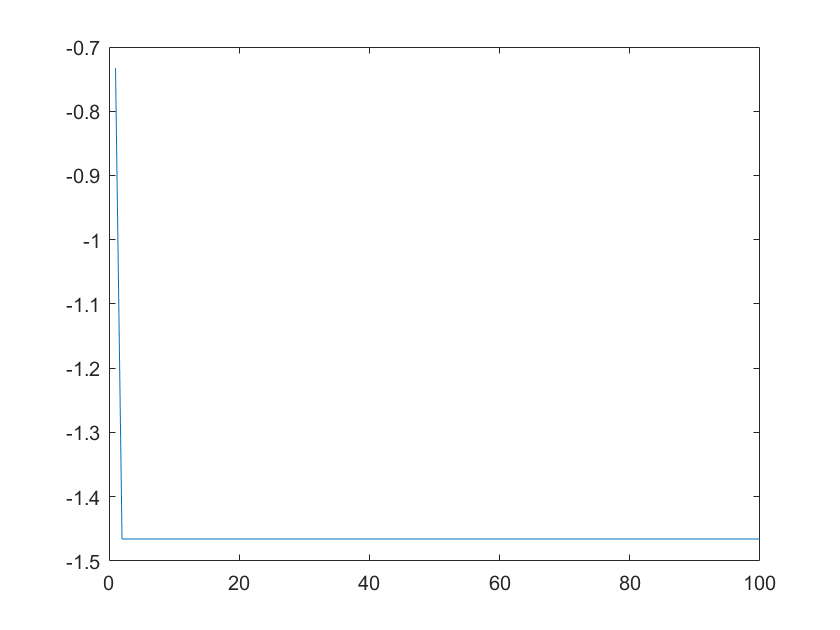


plot(y)


% startPoint = [25.0;-6.8;1];
startPoint = [25;-20;10];
% endPoint = [45.72;-4.6;1];
endPoint = [45;-20;10];

[viaPoint1,viaPoint2] = gen_viapoint(startPoint,endPoint)

viaPoint1 =    25.0000
  -20.0000
   26.5000


viaPoint2 =    45.0000
  -20.0000
   26.5000


pointList = [startPoint,viaPoint1,viaPoint2,endPoint];
vInit = [[0;0;0],[0;0;0.76], [2;0;0]];
vEnd = [[0;0;0.76],[2;0;0],[0;0;0.76]];
tStart = [0 2 4];
tEnd = [2 4 6];
coefficientList = [];
p = 0

p = 0

q = 0

q = 0

start = 1

start = 1

%read initial joint positions here
Q1 = 0;
Q2 = -70;
Q3 = 0;
Q4 = -Q2-Q3-21-90;
Q5 = 0;
Q6 = 0;
[fba,e] = readFB(s,6)

Error using serial/fprintf (line 156)
Unexpected error: OBJ must be connected to the hardware with FOPEN..

Error in readFB (line 31)
    fprintf(s, '%s', 'fbk\n');

% read in the values for motor 
% [Q1old,Q2old,Q3old,Q4old,Q5old,Q6old] = [fba(3),fba(4),fba(1),fba(2),fba(6),fba(5)]
count = 1;
record = [];
record1 = [];
record2 = [];
Q1old = fba(3);
Q2old = fba(4);
Q3old = fba(1);
Q4old = fba(2);
Q5old = fba(6);
Q6old = fba(5);
record3 = [];
for i = 1:3
    sp = pointList(:,i);
    ep = pointList(:,i+1);
    vi = vInit(:,i);
    ve = vEnd(:,i);
    ts = tStart(i);
    te = tEnd(i);
    temp = [];
    temp2 = [];
    for j = 1:3
        temp(:,j) = gen_calculate(ts,te,ep(j,:),ve(j,:),sp(j,:),vi(j,:)); %calculate co-efficients for polynomial
    end
    temp;
    tic
    count1 = 0;
    for t = ts:0.01:te
            count = count + 1;
            position = [];
            orientation = [];
            velocity = [];
            angvel = [];
            for j = 1:3
                position(j) = cal_position(temp(:,j),t);
                velocity(j) = cal_velocity(temp(:,j),t);
            end
            
            positionx(count) = position(1);
            positiony(count) = position(2);
            positionz(count) = position(3);
            
            velocityx(count) = velocity(1);
            velocityy(count) = velocity(2);
            velocityz(count) = velocity(3);
    end
end


% example gen_calculate

% gen_calculate(tinit,tf,df,vf,dinit,vinit)

clc;
clear all;
ts = 0

ts = 0

te = 5

te = 5

test4 = gen_calculate(0,10,25,2,15,0)

test4 =    15.0000
         0
    0.1000
   -0.0000


test5 = gen_calculate(10,20,32,0,25,2)

test5 =   -20.0000
    7.6000
   -0.3700
    0.0060


test1 = gen_calculate2(0,4,15,25,5,2,0,0.1)

A =            1           0           0           0           0           0
           0           1           0           0           0           0
           0           0           2           0           0           0
           1           4          16          64         256        1024
           0           1           8          48         256        1280
           0           0           2          24         192        1280


test1 =    15.0000
    5.0000
         0
   -0.8000
    0.2516
   -0.0227



test3 = gen_calculate2(4,10,25,30,2,3,0.1,0.4)

A =            1           4          16          64         256        1024
           0           1           8          48         256        1280
           0           0           2          24         192        1280
           1          10         100        1000       10000      100000
           0           1          20         300        4000       50000
           0           0           2          60        1200       20000


test3 =    79.5679
  -55.1358
   19.8883
   -3.2540
    0.2469
   -0.0070


count2 = 0;
for t = ts:0.01:te
    count2 = count2 + 1;
    velocity(count2) = cal_velocity(test4,t)
    position(count2) = cal_position(test4,t)
end

velocity = 0

position = 15

velocity =          0    0.0020


position =    15.0000   15.0000


velocity =          0    0.0020    0.0040


position =    15.0000   15.0000   15.0000


velocity =          0    0.0020    0.0040    0.0060


position =    15.0000   15.0000   15.0000   15.0001


velocity =          0    0.0020    0.0040    0.0060    0.0080


position =    15.0000   15.0000   15.0000   15.0001   15.0002


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044


velocity =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440


position =    15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048


velocity = 1×24
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460


position = 1×24
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053


velocity = 1×25
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480


position = 1×25
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058


velocity = 1×26
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500


position = 1×26
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062


velocity = 1×27
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520


position = 1×27
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068


velocity = 1×28
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540


position = 1×28
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073


velocity = 1×29
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560


position = 1×29
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078


velocity = 1×30
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×30
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×31
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×31
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×32
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×32
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×33
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×33
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×34
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×34
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×35
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×35
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×36
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×36
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×37
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×37
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×38
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×38
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×39
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×39
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×40
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×40
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×41
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×41
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×42
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×42
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×43
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×43
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×44
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×44
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×45
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×45
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×46
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×46
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×47
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×47
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×48
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×48
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×49
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×49
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×50
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×50
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×51
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×51
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×52
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×52
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×53
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×53
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×54
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×54
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×55
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×55
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×56
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×56
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×57
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×57
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×58
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×58
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×59
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×59
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×60
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×60
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×61
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×61
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×62
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×62
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×63
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×63
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×64
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×64
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×65
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×65
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×66
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×66
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×67
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×67
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×68
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×68
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×69
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×69
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×70
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×70
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×71
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×71
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×72
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×72
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×73
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×73
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×74
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×74
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×75
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×75
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×76
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×76
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×77
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×77
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×78
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×78
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×79
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×79
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×80
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×80
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×81
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×81
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×82
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×82
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×83
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×83
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×84
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×84
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×85
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×85
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×86
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×86
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×87
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×87
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×88
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×88
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×89
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×89
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×90
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×90
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×91
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×91
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×92
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×92
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×93
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×93
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×94
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×94
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×95
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×95
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×96
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×96
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×97
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×97
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×98
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×98
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×99
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×99
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×100
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×100
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×101
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×101
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×102
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×102
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×103
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×103
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×104
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×104
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×105
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×105
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×106
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×106
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×107
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×107
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×108
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×108
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×109
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×109
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×110
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×110
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×111
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×111
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×112
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×112
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×113
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×113
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×114
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×114
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×115
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×115
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×116
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×116
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×117
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×117
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×118
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×118
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×119
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×119
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×120
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×120
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×121
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×121
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×122
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×122
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×123
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×123
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×124
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×124
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×125
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×125
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×126
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×126
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×127
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×127
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×128
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×128
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×129
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×129
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×130
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×130
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×131
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×131
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×132
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×132
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×133
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×133
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×134
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×134
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×135
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×135
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×136
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×136
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×137
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×137
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×138
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×138
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×139
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×139
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×140
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×140
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×141
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×141
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×142
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×142
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×143
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×143
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×144
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×144
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×145
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×145
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×146
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×146
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×147
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×147
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×148
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×148
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×149
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×149
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×150
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×150
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×151
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×151
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×152
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×152
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×153
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×153
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×154
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×154
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×155
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×155
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×156
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×156
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×157
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×157
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×158
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×158
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×159
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×159
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×160
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×160
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×161
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×161
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×162
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×162
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×163
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×163
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×164
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×164
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×165
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×165
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×166
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×166
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×167
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×167
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×168
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×168
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×169
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×169
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×170
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×170
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×171
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×171
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×172
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×172
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×173
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×173
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×174
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×174
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×175
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×175
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×176
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×176
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×177
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×177
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×178
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×178
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×179
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×179
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×180
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×180
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×181
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×181
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×182
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×182
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×183
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×183
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×184
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×184
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×185
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×185
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×186
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×186
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×187
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×187
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×188
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×188
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×189
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×189
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×190
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×190
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×191
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×191
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×192
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×192
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×193
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×193
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×194
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×194
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×195
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×195
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×196
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×196
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×197
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×197
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×198
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×198
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×199
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×199
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×200
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×200
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×201
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×201
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×202
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×202
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×203
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×203
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×204
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×204
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×205
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×205
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×206
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×206
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×207
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×207
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×208
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×208
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×209
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×209
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×210
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×210
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×211
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×211
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×212
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×212
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×213
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×213
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×214
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×214
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×215
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×215
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×216
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×216
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×217
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×217
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×218
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×218
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×219
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×219
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×220
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×220
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×221
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×221
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×222
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×222
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×223
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×223
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×224
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×224
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×225
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×225
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×226
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×226
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×227
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×227
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×228
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×228
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×229
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×229
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×230
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×230
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×231
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×231
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×232
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×232
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×233
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×233
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×234
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×234
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×235
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×235
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×236
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×236
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×237
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×237
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×238
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×238
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×239
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×239
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×240
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×240
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×241
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×241
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×242
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×242
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×243
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×243
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×244
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×244
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×245
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×245
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×246
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×246
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×247
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×247
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×248
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×248
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×249
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×249
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×250
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×250
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×251
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×251
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×252
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×252
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×253
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×253
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×254
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×254
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×255
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×255
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×256
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×256
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×257
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×257
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×258
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×258
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×259
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×259
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×260
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×260
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×261
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×261
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×262
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×262
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×263
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×263
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×264
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×264
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×265
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×265
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×266
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×266
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×267
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×267
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×268
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×268
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×269
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×269
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×270
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×270
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×271
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×271
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×272
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×272
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×273
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×273
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×274
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×274
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×275
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×275
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×276
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×276
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×277
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×277
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×278
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×278
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×279
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×279
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×280
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×280
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×281
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×281
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×282
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×282
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×283
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×283
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×284
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×284
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×285
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×285
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×286
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×286
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×287
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×287
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×288
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×288
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×289
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×289
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×290
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×290
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×291
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×291
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×292
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×292
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×293
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×293
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×294
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×294
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×295
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×295
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×296
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×296
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×297
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×297
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×298
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×298
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×299
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×299
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×300
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×300
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×301
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×301
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×302
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×302
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×303
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×303
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×304
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×304
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×305
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×305
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×306
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×306
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×307
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×307
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×308
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×308
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×309
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×309
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×310
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×310
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×311
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×311
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×312
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×312
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×313
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×313
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×314
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×314
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×315
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×315
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×316
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×316
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×317
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×317
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×318
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×318
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×319
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×319
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×320
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×320
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×321
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×321
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×322
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×322
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×323
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×323
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×324
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×324
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×325
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×325
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×326
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×326
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×327
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×327
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×328
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×328
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×329
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×329
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×330
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×330
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×331
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×331
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×332
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×332
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×333
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×333
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×334
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×334
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×335
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×335
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×336
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×336
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×337
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×337
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×338
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×338
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×339
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×339
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×340
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×340
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×341
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×341
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×342
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×342
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×343
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×343
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×344
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×344
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×345
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×345
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×346
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×346
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×347
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×347
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×348
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×348
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×349
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×349
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×350
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×350
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×351
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×351
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×352
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×352
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×353
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×353
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×354
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×354
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×355
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×355
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×356
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×356
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×357
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×357
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×358
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×358
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×359
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×359
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×360
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×360
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×361
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×361
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×362
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×362
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×363
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×363
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×364
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×364
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×365
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×365
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×366
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×366
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×367
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×367
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×368
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×368
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×369
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×369
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×370
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×370
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×371
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×371
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×372
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×372
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×373
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×373
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×374
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×374
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×375
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×375
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×376
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×376
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×377
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×377
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×378
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×378
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×379
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×379
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×380
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×380
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×381
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×381
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×382
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×382
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×383
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×383
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×384
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×384
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×385
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×385
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×386
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×386
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×387
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×387
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×388
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×388
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×389
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×389
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×390
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×390
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×391
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×391
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×392
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×392
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×393
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×393
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×394
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×394
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×395
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×395
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×396
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×396
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×397
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×397
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×398
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×398
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×399
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×399
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×400
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×400
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×401
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×401
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×402
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×402
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×403
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×403
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×404
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×404
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×405
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×405
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×406
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×406
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×407
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×407
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×408
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×408
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×409
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×409
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×410
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×410
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×411
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×411
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×412
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×412
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×413
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×413
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×414
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×414
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×415
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×415
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×416
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×416
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×417
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×417
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×418
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×418
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×419
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×419
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×420
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×420
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×421
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×421
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×422
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×422
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×423
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×423
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×424
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×424
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×425
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×425
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×426
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×426
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×427
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×427
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×428
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×428
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×429
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×429
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×430
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×430
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×431
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×431
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×432
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×432
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×433
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×433
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×434
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×434
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×435
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×435
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×436
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×436
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×437
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×437
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×438
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×438
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×439
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×439
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×440
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×440
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×441
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×441
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×442
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×442
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×443
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×443
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×444
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×444
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×445
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×445
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×446
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×446
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×447
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×447
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×448
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×448
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×449
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×449
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×450
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×450
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×451
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×451
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×452
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×452
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×453
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×453
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×454
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×454
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×455
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×455
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×456
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×456
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×457
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×457
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×458
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×458
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×459
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×459
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×460
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×460
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×461
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×461
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×462
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×462
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×463
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×463
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×464
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×464
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×465
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×465
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×466
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×466
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×467
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×467
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×468
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×468
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×469
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×469
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×470
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×470
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×471
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×471
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×472
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×472
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×473
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×473
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×474
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×474
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×475
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×475
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×476
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×476
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×477
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×477
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×478
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×478
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×479
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×479
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×480
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×480
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×481
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×481
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×482
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×482
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×483
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×483
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×484
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×484
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×485
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×485
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×486
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×486
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×487
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×487
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×488
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×488
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×489
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×489
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×490
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×490
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×491
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×491
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×492
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×492
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×493
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×493
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×494
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×494
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×495
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×495
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×496
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×496
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×497
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×497
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×498
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×498
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×499
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×499
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×500
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×500
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×501
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×501
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084



ts = 5

ts = 5

te = 7

te = 7

for t = ts:0.01:te
    count2 = count2+1;
    velocity(count2) = cal_velocity(test5,t)
    position(count2) = cal_position(test5,t)
    
end

velocity = 1×502
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×502
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×503
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×503
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×504
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×504
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×505
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×505
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×506
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×506
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×507
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×507
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×508
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×508
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×509
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×509
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×510
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×510
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×511
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×511
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×512
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×512
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×513
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×513
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×514
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×514
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×515
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×515
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×516
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×516
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×517
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×517
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×518
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×518
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×519
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×519
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×520
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×520
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×521
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×521
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×522
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×522
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×523
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×523
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×524
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×524
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×525
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×525
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×526
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×526
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×527
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×527
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×528
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×528
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×529
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×529
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×530
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×530
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×531
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×531
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×532
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×532
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×533
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×533
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×534
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×534
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×535
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×535
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×536
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×536
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×537
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×537
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×538
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×538
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×539
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×539
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×540
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×540
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×541
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×541
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×542
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×542
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×543
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×543
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×544
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×544
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×545
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×545
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×546
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×546
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×547
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×547
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×548
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×548
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×549
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×549
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×550
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×550
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×551
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×551
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×552
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×552
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×553
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×553
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×554
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×554
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×555
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×555
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×556
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×556
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×557
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×557
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×558
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×558
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×559
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×559
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×560
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×560
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×561
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×561
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×562
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×562
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×563
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×563
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×564
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×564
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×565
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×565
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×566
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×566
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×567
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×567
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×568
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×568
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×569
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×569
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×570
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×570
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×571
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×571
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×572
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×572
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×573
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×573
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×574
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×574
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×575
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×575
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×576
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×576
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×577
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×577
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×578
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×578
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×579
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×579
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×580
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×580
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×581
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×581
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×582
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×582
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×583
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×583
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×584
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×584
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×585
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×585
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×586
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×586
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×587
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×587
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×588
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×588
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×589
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×589
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×590
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×590
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×591
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×591
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×592
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×592
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×593
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×593
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×594
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×594
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×595
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×595
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×596
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×596
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×597
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×597
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×598
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×598
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×599
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×599
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×600
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×600
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×601
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×601
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×602
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×602
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×603
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×603
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×604
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×604
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×605
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×605
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×606
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×606
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×607
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×607
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×608
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×608
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×609
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×609
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×610
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×610
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×611
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×611
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×612
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×612
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×613
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×613
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×614
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×614
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×615
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×615
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×616
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×616
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×617
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×617
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×618
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×618
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×619
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×619
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×620
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×620
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×621
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×621
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×622
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×622
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×623
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×623
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×624
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×624
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×625
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×625
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×626
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×626
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×627
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×627
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×628
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×628
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×629
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×629
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×630
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×630
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×631
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×631
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×632
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×632
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×633
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×633
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×634
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×634
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×635
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×635
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×636
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×636
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×637
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×637
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×638
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×638
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×639
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×639
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×640
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×640
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×641
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×641
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×642
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×642
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×643
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×643
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×644
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×644
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×645
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×645
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×646
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×646
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×647
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×647
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×648
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×648
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×649
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×649
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×650
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×650
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×651
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×651
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×652
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×652
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×653
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×653
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×654
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×654
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×655
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×655
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×656
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×656
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×657
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×657
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×658
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×658
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×659
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×659
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×660
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×660
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×661
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×661
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×662
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×662
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×663
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×663
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×664
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×664
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×665
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×665
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×666
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×666
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×667
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×667
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×668
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×668
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×669
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×669
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×670
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×670
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×671
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×671
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×672
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×672
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×673
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×673
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×674
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×674
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×675
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×675
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×676
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×676
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×677
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×677
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×678
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×678
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×679
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×679
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×680
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×680
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×681
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×681
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×682
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×682
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×683
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×683
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×684
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×684
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×685
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×685
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×686
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×686
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×687
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×687
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×688
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×688
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×689
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×689
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×690
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×690
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×691
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×691
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×692
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×692
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×693
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×693
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×694
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×694
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×695
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×695
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×696
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×696
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×697
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×697
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×698
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×698
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×699
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×699
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×700
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×700
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×701
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×701
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


velocity = 1×702
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580


position = 1×702
   15.0000   15.0000   15.0000   15.0001   15.0002   15.0002   15.0004   15.0005   15.0006   15.0008   15.0010   15.0012   15.0014   15.0017   15.0020   15.0023   15.0026   15.0029   15.0032   15.0036   15.0040   15.0044   15.0048   15.0053   15.0058   15.0062   15.0068   15.0073   15.0078   15.0084


clear all
clc
% startPoint = [25.0;-6.8;1];
startPoint = [15;25;10];
% endPoint = [45.72;-4.6;1];
endPoint = [35;19;10];

[viaPoint1,viaPoint2] = gen_viapoint(startPoint,endPoint)

viaPoint1 =    15.0000
   25.0000
   26.5000


viaPoint2 =    35.0000
   19.0000
   26.5000


pointList = [startPoint,viaPoint1,viaPoint2,endPoint];
vInit = [[0;0;0],[0;0;0.76], [2;0;0]];
vEnd = [[0;0;0.76],[2;0;0],[0;0;0.76]];
tStart = [0 5 10];
tEnd = [5 10 15];
coefficientList = [];
p = 0

p = 0

q = 0

q = 0

start = 1

start = 1

count1 = 0

count1 = 0

for i = 1:3
    sp = pointList(:,i);
    ep = pointList(:,i+1);
    vi = vInit(:,i);
    ve = vEnd(:,i);
    ts = tStart(i);
    te = tEnd(i);
    temp = [];
    temp2 = [];
    for j = 1:3
        temp(:,j) = gen_calculate(ts,te,ep(j,:),ve(j,:),sp(j,:),vi(j,:)); %calculate co-efficients for polynomial
    end
    temp;
    tic
    
    for t = ts:0.01:te
            count1 = count1 + 1;
            position = [];
            orientation = [];
            velocity = [];
            angvel = [];
            for j = 1:3
                position(j) = cal_position(temp(:,j),t);
                velocity(j) = cal_velocity(temp(:,j),t);
            end
            
            positionx(count1) = position(1);
            positiony(count1) = position(2);
            positionz(count1) = position(3);
            
            velocityx(count1) = velocity(1);
            velocityy(count1) = velocity(2);
            velocityz(count1) = velocity(3);
            
            [Q1,Q2,Q3,Q4,Q5] = invkinematics(position(1),position(2),position(3),1)
            
            Q1c(count1) = Q1;
            Q2c(count1) = Q2;
            Q3c(count1) = Q3;
            Q4c(count1) = Q4;
            Q5c(count1) = Q5;
            
            velocitycomb = [velocity(1),velocity(2),velocity(3),0,0,-1]
            
            [Q1dot,Q2dot,Q3dot,Q4dot,Q5dot] = invJacobian(velocitycomb,Q1,Q2,Q3,Q4,Q5)
            
            Q1d(count1) = Q1dot;
            Q2d(count1) = Q2dot;
            Q3d(count1) = Q3dot;
            Q4d(count1) = Q4dot;
            Q5d(count1) = Q5dot;
            
            vectorout = jacobian(Q1,Q2,Q3,Q4,Q5,Q1dot,Q2dot,Q3dot,Q4dot,Q5dot);
            
            ab(count1,1:6) = vectorout;
    end
end

Q1 = 59.0362

Q2 = -78.8940

Q3 = 99.5877

Q4 = -45.6937

Q5 = 0

velocitycomb =      0     0     0     0     0    -1


l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    20.3485   14.2401   -8.9612  -15.7142         0
   26.5452  -10.9160   -5.1766   12.0459         0
         0  -33.4471   -7.9355         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Jpseudoinv =     0.0511   -0.0015    0.0469    0.5003    0.6526   -0.0000
   -0.0274    0.0210   -0.0688   -0.4152   -0.5417         0
    0.1153   -0.0884    0.1640    1.7502    2.2832   -0.0000
   -0.0880    0.0674   -0.0952   -0.7266   -0.9478    0.0000
    0.0511   -0.0015    0.0469    0.5003    0.6526   -1.0000


Jpseudoinv =     0.0511   -0.0015    0.0469    0.5003    0.6526   -0.0000
   -0.0274    0.0210   -0.0688   -0.4152   -0.5417         0
    0.1153   -0.0884    0.1640    1.7502    2.2832   -0.0000
   -0.0880    0.0674   -0.0952   -0.7266   -0.9478    0.0000
    0.0511   -0.0015    0.0469    0.5003    0.6526   -1.0000


Q1dot = 1.1102e-16

Q2dot = 0

Q3dot = 4.4409e-16

Q4dot = -1.1102e-16

Q5dot = 1

l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    20.3485   14.2401   -8.9612  -15.7142         0
   26.5452  -10.9160   -5.1766   12.0459         0
         0  -33.4471   -7.9355         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Q1 = 59.0362

Q2 = -78.8941

Q3 = 99.5874

Q4 = -45.6932

Q5 = 0

velocitycomb =          0         0    0.0365         0         0   -1.0000


l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    20.3407   14.2454   -8.9587  -15.7142         0
   26.5350  -10.9200   -5.1785   12.0459         0
         0  -33.4343   -7.9239         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Jpseudoinv =     0.0511   -0.0015    0.0468    0.4996    0.6518         0
   -0.0273    0.0209   -0.0687   -0.4141   -0.5402         0
    0.1151   -0.0882    0.1638    1.7473    2.2794         0
   -0.0878    0.0673   -0.0951   -0.7248   -0.9456         0
    0.0511   -0.0015    0.0468    0.4996    0.6518   -1.0000


Jpseudoinv =     0.0511   -0.0015    0.0468    0.4996    0.6518         0
   -0.0273    0.0209   -0.0687   -0.4141   -0.5402         0
    0.1151   -0.0882    0.1638    1.7473    2.2794         0
   -0.0878    0.0673   -0.0951   -0.7248   -0.9456         0
    0.0511   -0.0015    0.0468    0.4996    0.6518   -1.0000


Q1dot = 0.0017

Q2dot = -0.0025

Q3dot = 0.0060

Q4dot = -0.0035

Q5dot = 1.0017

l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    20.3407   14.2454   -8.9587  -15.7142         0
   26.5350  -10.9200   -5.1785   12.0459         0
         0  -33.4343   -7.9239         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Q1 = 59.0362

Q2 = -78.8945

Q3 = 99.5866

Q4 = -45.6920

Q5 = 0

velocitycomb =          0         0    0.0728         0         0   -1.0000


l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    20.3173   14.2613   -8.9509  -15.7142         0
   26.5044  -10.9321   -5.1845   12.0459         0
         0  -33.3957   -7.8892         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Jpseudoinv =     0.0510   -0.0014    0.0467    0.4978    0.6493   -0.0000
   -0.0271    0.0207   -0.0685   -0.4108   -0.5358    0.0000
    0.1146   -0.0878    0.1632    1.7388    2.2683         0
   -0.0875    0.0671   -0.0947   -0.7196   -0.9388    0.0000
    0.0510   -0.0014    0.0467    0.4978    0.6493   -1.0000


Jpseudoinv =     0.0510   -0.0014    0.0467    0.4978    0.6493   -0.0000
   -0.0271    0.0207   -0.0685   -0.4108   -0.5358    0.0000
    0.1146   -0.0878    0.1632    1.7388    2.2683         0
   -0.0875    0.0671   -0.0947   -0.7196   -0.9388    0.0000
    0.0510   -0.0014    0.0467    0.4978    0.6493   -1.0000


Q1dot = 0.0034

Q2dot = -0.0050

Q3dot = 0.0119

Q4dot = -0.0069

Q5dot = 1.0034

l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    20.3173   14.2613   -8.9509  -15.7142         0
   26.5044  -10.9321   -5.1845   12.0459         0
         0  -33.3957   -7.8892         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Q1 = 59.0362

Q2 = -78.8952

Q3 = 99.5852

Q4 = -45.6900

Q5 = 0

velocitycomb =          0         0    0.1090         0         0   -1.0000


l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    20.2782   14.2875   -8.9382  -15.7142         0
   26.4535  -10.9523   -5.1942   12.0459         0
         0  -33.3316   -7.8313         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Jpseudoinv =     0.0508   -0.0012    0.0466    0.4947    0.6453         0
   -0.0267    0.0205   -0.0682   -0.4052   -0.5286    0.0000
    0.1136   -0.0871    0.1624    1.7247    2.2499   -0.0000
   -0.0869    0.0666   -0.0942   -0.7111   -0.9276         0
    0.0508   -0.0012    0.0466    0.4947    0.6453   -1.0000


Jpseudoinv =     0.0508   -0.0012    0.0466    0.4947    0.6453         0
   -0.0267    0.0205   -0.0682   -0.4052   -0.5286    0.0000
    0.1136   -0.0871    0.1624    1.7247    2.2499   -0.0000
   -0.0869    0.0666   -0.0942   -0.7111   -0.9276         0
    0.0508   -0.0012    0.0466    0.4947    0.6453   -1.0000


Q1dot = 0.0051

Q2dot = -0.0074

Q3dot = 0.0177

Q4dot = -0.0103

Q5dot = 1.0051

l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    20.2782   14.2875   -8.9382  -15.7142         0
   26.4535  -10.9523   -5.1942   12.0459         0
         0  -33.3316   -7.8313         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Q1 = 59.0362

Q2 = -78.8961

Q3 = 99.5833

Q4 = -45.6871

Q5 = 0

velocitycomb =          0         0    0.1451         0         0   -1.0000


l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    20.2237   14.3240   -8.9206  -15.7142         0
   26.3823  -10.9802   -5.2077   12.0459         0
         0  -33.2418   -7.7504         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Jpseudoinv =     0.0506   -0.0009    0.0464    0.4904    0.6398         0
   -0.0262    0.0201   -0.0677   -0.3976   -0.5187    0.0000
    0.1124   -0.0861    0.1612    1.7052    2.2245         0
   -0.0862    0.0660   -0.0935   -0.6993   -0.9122    0.0000
    0.0506   -0.0009    0.0464    0.4904    0.6398   -1.0000


Jpseudoinv =     0.0506   -0.0009    0.0464    0.4904    0.6398         0
   -0.0262    0.0201   -0.0677   -0.3976   -0.5187    0.0000
    0.1124   -0.0861    0.1612    1.7052    2.2245         0
   -0.0862    0.0660   -0.0935   -0.6993   -0.9122    0.0000
    0.0506   -0.0009    0.0464    0.4904    0.6398   -1.0000


Q1dot = 0.0067

Q2dot = -0.0098

Q3dot = 0.0234

Q4dot = -0.0136

Q5dot = 1.0067

l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    20.2237   14.3240   -8.9206  -15.7142         0
   26.3823  -10.9802   -5.2077   12.0459         0
         0  -33.2418   -7.7504         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Q1 = 59.0362

Q2 = -78.8973

Q3 = 99.5808

Q4 = -45.6835

Q5 = 0

velocitycomb =          0         0    0.1810         0         0   -1.0000


l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    20.1535   14.3705   -8.8982  -15.7142         0
   26.2908  -11.0159   -5.2249   12.0459         0
         0  -33.1266   -7.6466         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Jpseudoinv =     0.0503   -0.0005    0.0461    0.4851    0.6328         0
   -0.0256    0.0196   -0.0670   -0.3880   -0.5061    0.0000
    0.1107   -0.0849    0.1597    1.6808    2.1927         0
   -0.0852    0.0653   -0.0926   -0.6845   -0.8929    0.0000
    0.0503   -0.0005    0.0461    0.4851    0.6328   -1.0000


Jpseudoinv =     0.0503   -0.0005    0.0461    0.4851    0.6328         0
   -0.0256    0.0196   -0.0670   -0.3880   -0.5061    0.0000
    0.1107   -0.0849    0.1597    1.6808    2.1927         0
   -0.0852    0.0653   -0.0926   -0.6845   -0.8929    0.0000
    0.0503   -0.0005    0.0461    0.4851    0.6328   -1.0000


Q1dot = 0.0083

Q2dot = -0.0121

Q3dot = 0.0289

Q4dot = -0.0168

Q5dot = 1.0083

l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    20.1535   14.3705   -8.8982  -15.7142         0
   26.2908  -11.0159   -5.2249   12.0459         0
         0  -33.1266   -7.6466         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Q1 = 59.0362

Q2 = -78.8988

Q3 = 99.5778

Q4 = -45.6790

Q5 = 0

velocitycomb =          0         0    0.2168         0         0   -1.0000


l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    20.0679   14.4269   -8.8713  -15.7142         0
   26.1791  -11.0591   -5.2455   12.0459         0
         0  -32.9858   -7.5197         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Jpseudoinv =     0.0500   -0.0001    0.0458    0.4787    0.6245    0.0000
   -0.0248    0.0190   -0.0663   -0.3765   -0.4912         0
    0.1088   -0.0834    0.1579    1.6518    2.1548         0
   -0.0840    0.0644   -0.0916   -0.6668   -0.8699   -0.0000
    0.0500   -0.0001    0.0458    0.4787    0.6245   -1.0000


Jpseudoinv =     0.0500   -0.0001    0.0458    0.4787    0.6245    0.0000
   -0.0248    0.0190   -0.0663   -0.3765   -0.4912         0
    0.1088   -0.0834    0.1579    1.6518    2.1548         0
   -0.0840    0.0644   -0.0916   -0.6668   -0.8699   -0.0000
    0.0500   -0.0001    0.0458    0.4787    0.6245   -1.0000


Q1dot = 0.0099

Q2dot = -0.0144

Q3dot = 0.0342

Q4dot = -0.0199

Q5dot = 1.0099

l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    20.0679   14.4269   -8.8713  -15.7142         0
   26.1791  -11.0591   -5.2455   12.0459         0
         0  -32.9858   -7.5197         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Q1 = 59.0362

Q2 = -78.9005

Q3 = 99.5742

Q4 = -45.6737

Q5 = 0

velocitycomb =          0         0    0.2525         0         0   -1.0000


l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    19.9667   14.4928   -8.8402  -15.7142         0
   26.0471  -11.1096   -5.2694   12.0459         0
         0  -32.8195   -7.3699         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Jpseudoinv =     0.0496    0.0004    0.0454    0.4714    0.6150   -0.0000
   -0.0239    0.0184   -0.0655   -0.3634   -0.4741    0.0000
    0.1066   -0.0817    0.1558    1.6184    2.1113         0
   -0.0827    0.0634   -0.0904   -0.6466   -0.8435   -0.0000
    0.0496    0.0004    0.0454    0.4714    0.6150   -1.0000


Jpseudoinv =     0.0496    0.0004    0.0454    0.4714    0.6150   -0.0000
   -0.0239    0.0184   -0.0655   -0.3634   -0.4741    0.0000
    0.1066   -0.0817    0.1558    1.6184    2.1113         0
   -0.0827    0.0634   -0.0904   -0.6466   -0.8435   -0.0000
    0.0496    0.0004    0.0454    0.4714    0.6150   -1.0000


Q1dot = 0.0115

Q2dot = -0.0165

Q3dot = 0.0393

Q4dot = -0.0228

Q5dot = 1.0115

l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    19.9667   14.4928   -8.8402  -15.7142         0
   26.0471  -11.1096   -5.2694   12.0459         0
         0  -32.8195   -7.3699         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Q1 = 59.0362

Q2 = -78.9025

Q3 = 99.5702

Q4 = -45.6677

Q5 = 0

velocitycomb =          0         0    0.2880         0         0   -1.0000


l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    19.8500   14.5678   -8.8051  -15.7142         0
   25.8948  -11.1671   -5.2962   12.0459         0
         0  -32.6277   -7.1971         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Jpseudoinv =     0.0492    0.0009    0.0450    0.4633    0.6044    0.0000
   -0.0230    0.0176   -0.0645   -0.3488   -0.4550    0.0000
    0.1042   -0.0799    0.1535    1.5813    2.0629         0
   -0.0812    0.0622   -0.0890   -0.6241   -0.8142    0.0000
    0.0492    0.0009    0.0450    0.4633    0.6044   -1.0000


Jpseudoinv =     0.0492    0.0009    0.0450    0.4633    0.6044    0.0000
   -0.0230    0.0176   -0.0645   -0.3488   -0.4550    0.0000
    0.1042   -0.0799    0.1535    1.5813    2.0629         0
   -0.0812    0.0622   -0.0890   -0.6241   -0.8142    0.0000
    0.0492    0.0009    0.0450    0.4633    0.6044   -1.0000


Q1dot = 0.0130

Q2dot = -0.0186

Q3dot = 0.0442

Q4dot = -0.0256

Q5dot = 1.0130

l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    19.8500   14.5678   -8.8051  -15.7142         0
   25.8948  -11.1671   -5.2962   12.0459         0
         0  -32.6277   -7.1971         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Q1 = 59.0362

Q2 = -78.9047

Q3 = 99.5655

Q4 = -45.6608

Q5 = 0

velocitycomb =          0         0    0.3234         0         0   -1.0000


l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J =    19.7177   14.6516   -8.7665  -15.7142         0
   25.7223  -11.2314   -5.3259   12.0459         0
         0  -32.4102   -7.0013         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Jpseudoinv =     0.0487    0.0015    0.0445    0.4545    0.5929         0
   -0.0219    0.0168   -0.0635   -0.3329   -0.4342         0
    0.1015   -0.0778    0.1510    1.5409    2.0101         0
   -0.0796    0.0610   -0.0875   -0.5997   -0.7823         0
    0.0487    0.0015    0.0445    0.4545    0.5929   -1.0000


Jpseudoinv = 5×6
    0.0487    0.0015    0.0445    0.4545    0.5929         0
   -0.0219    0.0168   -0.0635   -0.3329   -0.4342         0
    0.1015   -0.0778    0.1510    1.5409    2.0101         0
   -0.0796    0.0610   -0.0875   -0.5997   -0.7823         0
    0.0487    0.0015    0.0445    0.4545    0.5929   -1.0000


Q1dot = 0.0144

Q2dot = -0.0205

Q3dot = 0.0488

Q4dot = -0.0283

Q5dot = 1.0144

l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J = 6×5
   19.7177   14.6516   -8.7665  -15.7142         0
   25.7223  -11.2314   -5.3259   12.0459         0
         0  -32.4102   -7.0013         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Q1 = 59.0362

Q2 = -78.9072

Q3 = 99.5604

Q4 = -45.6531

Q5 = 0

velocitycomb = 1×6
         0         0    0.3586         0         0   -1.0000


l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J = 6×5
   19.5698   14.7438   -8.7246  -15.7142         0
   25.5293  -11.3020   -5.3580   12.0459         0
         0  -32.1672   -6.7825         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Jpseudoinv = 5×6
    0.0482    0.0022    0.0441    0.4451    0.5806         0
   -0.0208    0.0159   -0.0624   -0.3158   -0.4119         0
    0.0987   -0.0756    0.1483    1.4976    1.9537         0
   -0.0779    0.0597   -0.0860   -0.5734   -0.7481         0
    0.0482    0.0022    0.0441    0.4451    0.5806   -1.0000


Jpseudoinv = 5×6
    0.0482    0.0022    0.0441    0.4451    0.5806         0
   -0.0208    0.0159   -0.0624   -0.3158   -0.4119         0
    0.0987   -0.0756    0.1483    1.4976    1.9537         0
   -0.0779    0.0597   -0.0860   -0.5734   -0.7481         0
    0.0482    0.0022    0.0441    0.4451    0.5806   -1.0000


Q1dot = 0.0158

Q2dot = -0.0224

Q3dot = 0.0532

Q4dot = -0.0308

Q5dot = 1.0158

l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J = 6×5
   19.5698   14.7438   -8.7246  -15.7142         0
   25.5293  -11.3020   -5.3580   12.0459         0
         0  -32.1672   -6.7825         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Q1 = 59.0362

Q2 = -78.9100

Q3 = 99.5547

Q4 = -45.6447

Q5 = 0

velocitycomb = 1×6
         0         0    0.3937         0         0   -1.0000


l1 = 19.8000

l2 = 27.2000

l3 = 29.4000

l45 = 19.8000

J = 6×5
   19.4063   14.8439   -8.6800  -15.7142         0
   25.3160  -11.3788   -5.3922   12.0459         0
         0  -31.8984   -6.5407         0         0
         0    0.6084    0.6084    0.6084         0
         0    0.7936    0.7936    0.7936         0
    1.0000         0         0         0   -1.0000


Jpseudoinv = 5×6
    0.0477    0.0029    0.0436    0.4351    0.5677         0
   -0.0196    0.0150   -0.0612   -0.2977   -0.3884         0
    0.0957   -0.0733    0.1455    1.4519    1.8941   -0.0000
   -0.0760    0.0583   -0.0843   -0.5458   -0.7120         0
    0.0477    0.0029    0.0436    0.4351    0.5677   -1.0000


Jpseudoinv = 5×6
    0.0477    0.0029    0.0436    0.4351    0.5677         0
   -0.0196    0.0150   -0.0612   -0.2977   -0.3884         0
    0.0957   -0.0733    0.1455    1.4519    1.8941   -0.0000
   -0.0760    0.0583   -0.0843   -0.5458   -0.7120         0
    0.0477    0.0029    0.0436    0.4351    0.5677   -1.0000


Q1dot = 0.0172

Q2dot = -0.0241

Q3dot = 0.0573

Q4dot = -0.0332


%% seems like I can use the pseudo inverse, and filter out the output from there, 

plot(positionx)
